# **第七章 变量降维与特征选择**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

        在前面的章节里，我们知道若原始数据集中输入特征的个数较多，尤其是输入特征的个数远大于样本数时，模型很容易陷入过拟合问题。 为了克服该问题，一个有效的方法是在建立模型之前，降低输入特征的维度。变量降维与特征选择均可以实现该目的，但是两者之间还存在一些细微的差别，具体如下：

- **变量降维（Dimension Reduction）：**将原始高维特征空间经过线性或非线性映射，投影到一个低维特征空间，实现维度的降低。低维特征空间中的每个新特征，都是原始高维特征中所有特征的线性或非线性组合。

- **特征选择（Feature Selection）：**利用一些评判方法对原始输入特征的重要性进行排序，保留较为重要的特征，剔除不重要的特征，实现维度的降低。选择出的特征组合是原始输入特征集合中的一个子集。**特征选择方法整体上可以分为两类：Filter类和Wrapper类。**Filter类特征选择方法`无需利用学习模型的性能，即可进行特征选择，主要依赖一些评价准则，如：相关系数、互信息、信息熵等；Wrapper类特征选择方法需要建立学习模型，通过模型的性能进行评价特征的优劣，如：前向/后向选择法、遗传算法等。`

`    接下来，主要介绍两种变量降维方法（主成分分析、偏最小二乘法）和一种特征选择方法（遗传算法）。`

## **7.1 主成分分析简介**

        主成分分析（Principal Component Analysis, PCA）是一种常用的数据降维技术。它通过线性变换将原始数据转换到一个新的坐标系统中，使得这个新坐标系统的第一个坐标轴上的方差最大（即数据的第一个主成分），第二个坐标轴上的方差次之，依此类推。这样，PCA可以减少数据集的维度，同时尽可能保留数据中的重要信息（方差）。

        如图1所示，PCA的基本思想是找到一个方向，使得数据在这个方向上的投影具有最大方差。这个方向就是数据的第一个主成分。接下来，找到一个与第一个主成分正交的方向，使得数据在这个新方向上的投影具有最大方差，这个方向是第二个主成分，依此类推。这样，PCA转换后的坐标轴能够最大程度地捕捉数据集中的变异性。

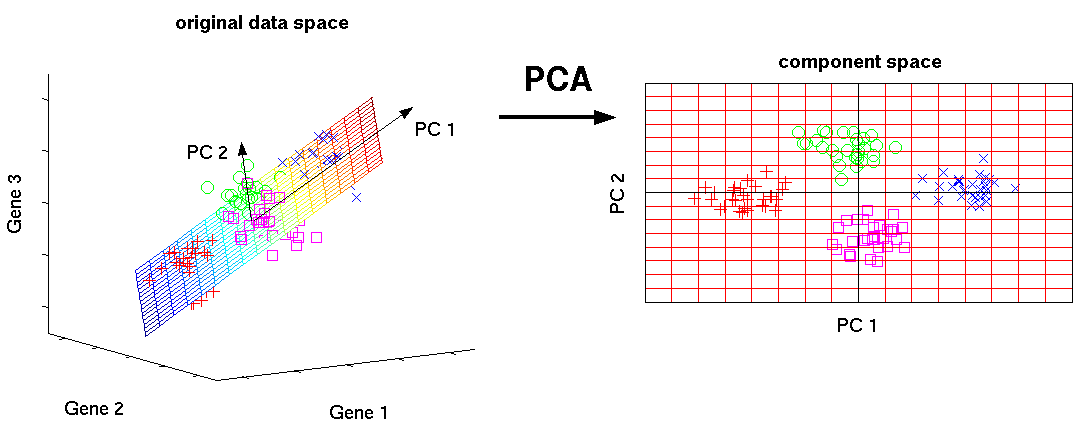

图1 主成分分析示意图

        主成分分析的算法步骤如下：

- **标准化数据：**对每一个维度（特征）进行标准化处理（减去均值，然后除以标准差）。这一步是为了确保每个特征在PCA转换中具有相同的重要性。

- **计算协方差矩阵：**对标准化后的数据集计算协方差矩阵。

- **计算协方差矩阵的特征值和特征向量：**计算协方差矩阵的特征值和对应的特征向量。特征值越大的特征向量，其对应的方向上数据的方差越大。

- **选择主成分：**根据特征值的大小选择前 *k* 个特征向量，这些特征向量就构成了数据的主成分。*k* 的选择取决于想要保留的原始数据方差的比例。

- **转换到新的空间：**使用选定的主成分构建一个转换矩阵，并用它来将原始数据集转换到新的特征空间。

## **7.2 偏最小二乘法简介**

         PCA虽然是一种强大的降维技术，但它也有局限性。PCA`方法提取出的前若干个主成分携带了原输入变量矩阵的大部分信息，消除了相互重叠部分的信息。并没有考虑主成分对输出变量的解释能力，``方差贡献率很小但对输出变量有很强解释能力的主成分将会被忽略掉``，这无疑会对校正模型的性能产生一定的影响。为了解决该问题，偏最小二乘法`（Partial Least Squares, PLS）被提了出来。

        偏最小二乘法结合了主成分分析（PCA）和多元线性回归的特点。它通过提取解释变量的成分（称为潜在变量或成分），这些成分既能够解释解释变量的方差，又与响应变量高度相关。这种方法尤其适用于解释变量数量多于观测数或解释变量间高度相关的情况。PLS与PCA的区别如图2所示。

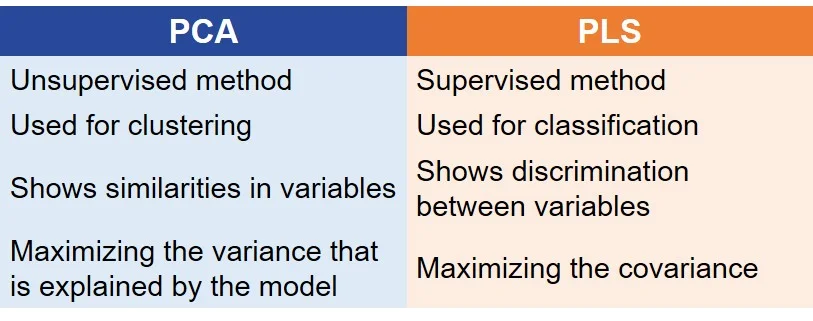

图2 PLS与PCA的区别

        PLS的算法步骤如下：

- **数据标准化：**将所有解释变量和响应变量标准化（通常是减去均值，除以标准差），确保每个变量具有相同的尺度。

- **提取第一个成分：**选择一个与响应变量协方差最大的解释变量线性组合作为第一个潜在变量（成分）。

- **回归和提取残差：**将解释变量和响应变量对第一个潜在变量进行回归，得到各自的残差。

- **提取更多的成分：**对残差重复步骤2和3，提取第二个、第三个等更多的潜在变量，直到达到预定的成分数量或解释的方差达到一个满意的水平。

- **构建预测模型：**使用提取的成分构建一个多元线性回归模型来预测响应变量。

- **模型验证：**通过交叉验证等方法验证模型的预测能力。

## **7.3 遗传算法简介**

        遗传算法（Genetic Algorithm, GA）是一种受自然选择原理启发的优化算法，其基本原理是仿效生物界中的“物竞天择、适者生存”的演化法则，通过模拟自然界中的遗传和自然选择机制，逐步进化出问题的最优解或近似最优解。它最初由美国Michigan大学的J. Holland教授于1967年提出。

        在介绍遗传算法的工作原理之前，先简要介绍几个基本的概念：

- **个体（individual）：**解空间中的任何一个可行解，都可以称之为一个“个体”。

- **种群（population）：**由若干个个体形成的一个集合，称之为一个“种群”。

- **适应度函数（fitness function）：**用于评价个体好坏程度的评价指标，将个体代入到适应度函数中，即可计算出该个体的适**应度函数值（fitness value）**。默认情况下，适应度函数值越大，表明对应的个体越“好“。

        遗传算法的工作过程如图3所示：

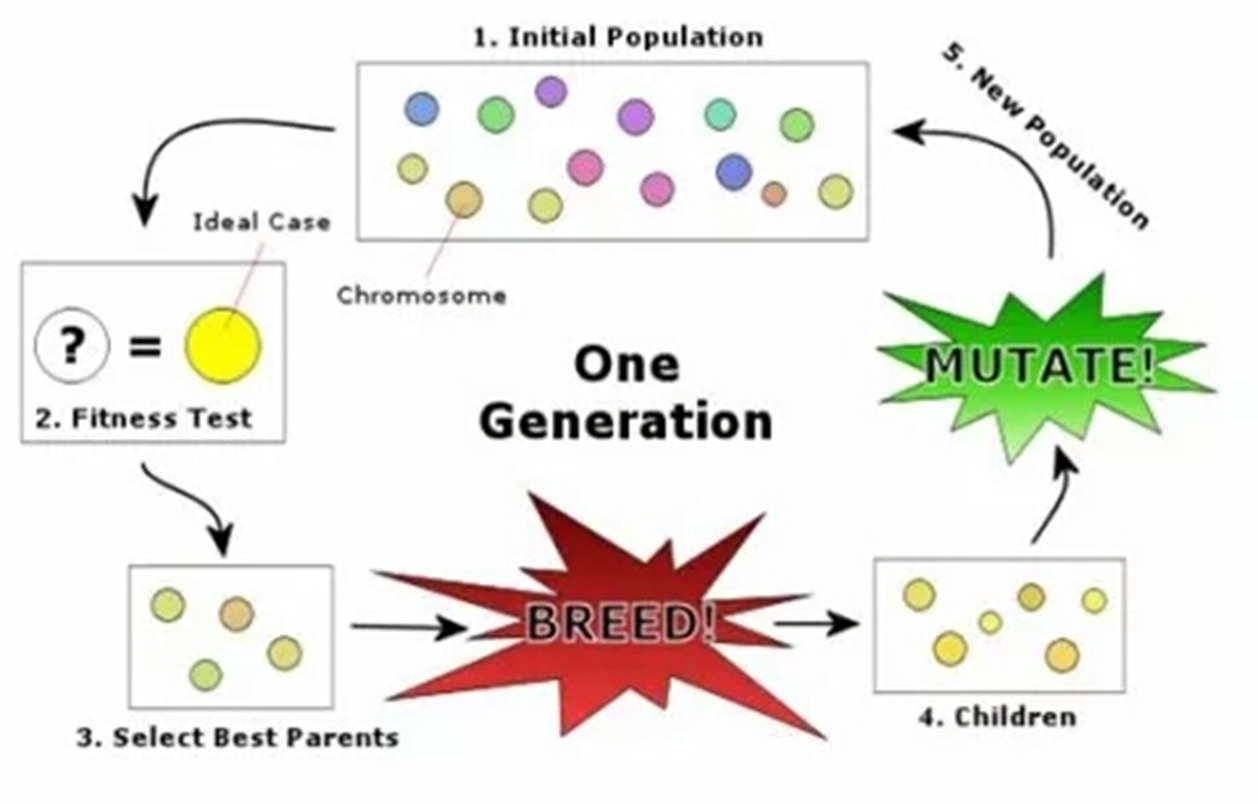

图3 遗传算法工作过程示意图

        主要包括如下几个步骤：

- ** 初始种群：**根据给定的种群规模大小，随机生成若干个个体，构成初始种群。

- **适应度评估：**针对每个个体，利用适应度函数对每个个体（解）进行评估，确定其适应度函数值。

- **选择（Selection）：**对所有个体按照适应度函数值从高到低降序排列，依据如图4所示的轮盘赌策略对个体进行选择，即适应度函数值大的个体被选中的概率也更高。

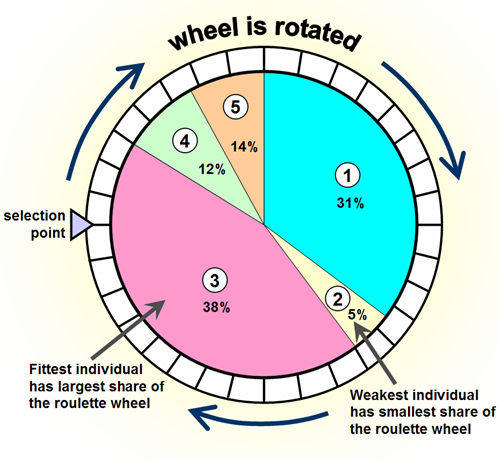

图4 轮盘赌选择操作的示意图

- **交叉（Crossover）：**从选择操作保留下来的个体中，随机选择两个个体作为父个体，模拟生物的杂交过程，通过交叉操作生成新的个体，交叉操作的过程如图5所示。

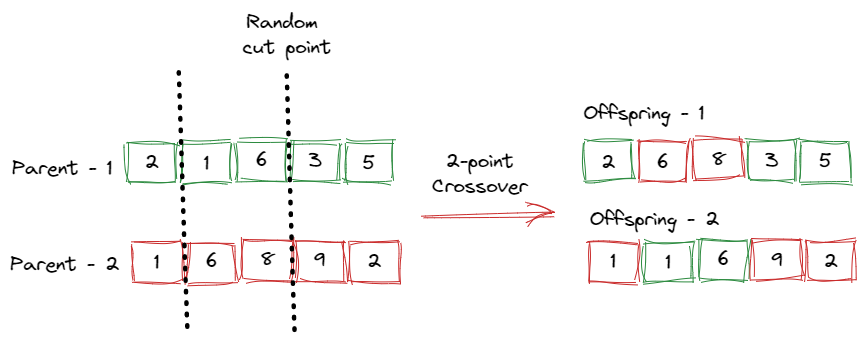

图5 交叉操作的示意图

- **变异（Mutation）：**以一定的概率随机修改个体的某些部分，增加种群的多样性。变异操作的过程如图6所示，具体来说，若变异点的值为“1”，则将其改为“0”，反之则将其改为“1”。

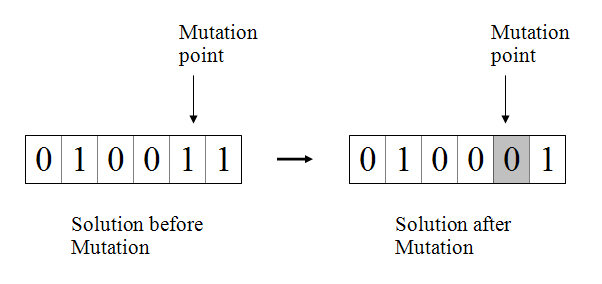

图6 变异操作的示意图

- **新一代种群：**通过选择、交叉和变异操作产生新一代种群。

- **终止条件：**重复上述过程，直到满足终止条件（如达到预定的迭代次数、找到足够好的解或适应度不再提高）。

## **7.4 案例1：基于PCA的变量降维——近红外光谱汽油辛烷值预测**

- **数据导入**

%% 导入数据
load spectra_data.mat

- **训练集/测试集划分**

temp = 1:60;
%%
x = 50;
% 训练集——x（0<x<60）个样本
P_train = NIR(temp(1:x),:);
T_train = octane(temp(1:x),:);

% 测试集——60-x个样本
P_test = NIR(temp(x+1:end),:);
T_test = octane(temp(x+1:end),:);

- **主成分分析**

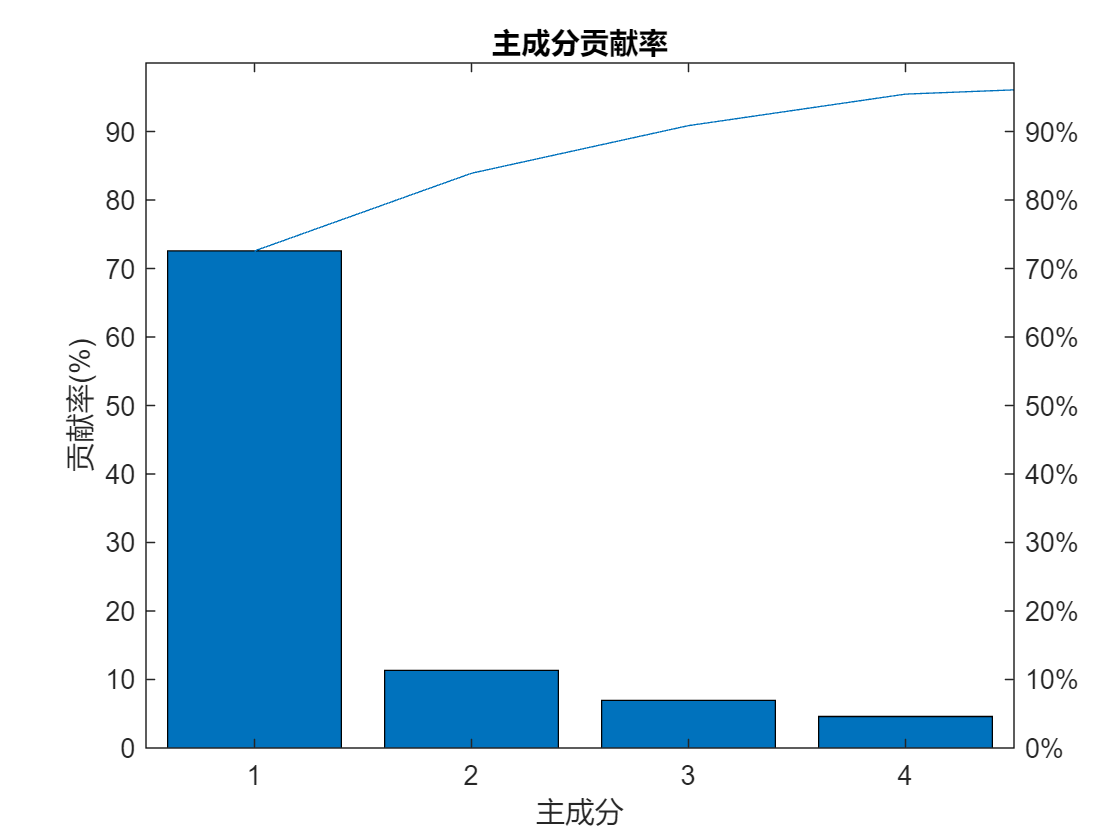

% 主成分贡献率分析
[~, ~, PCAVar] = pca(NIR);
figure
percent_explained = 100 * PCAVar / sum(PCAVar);
pareto(percent_explained)
xlabel('主成分')
ylabel('贡献率(%)')
title('主成分贡献率')

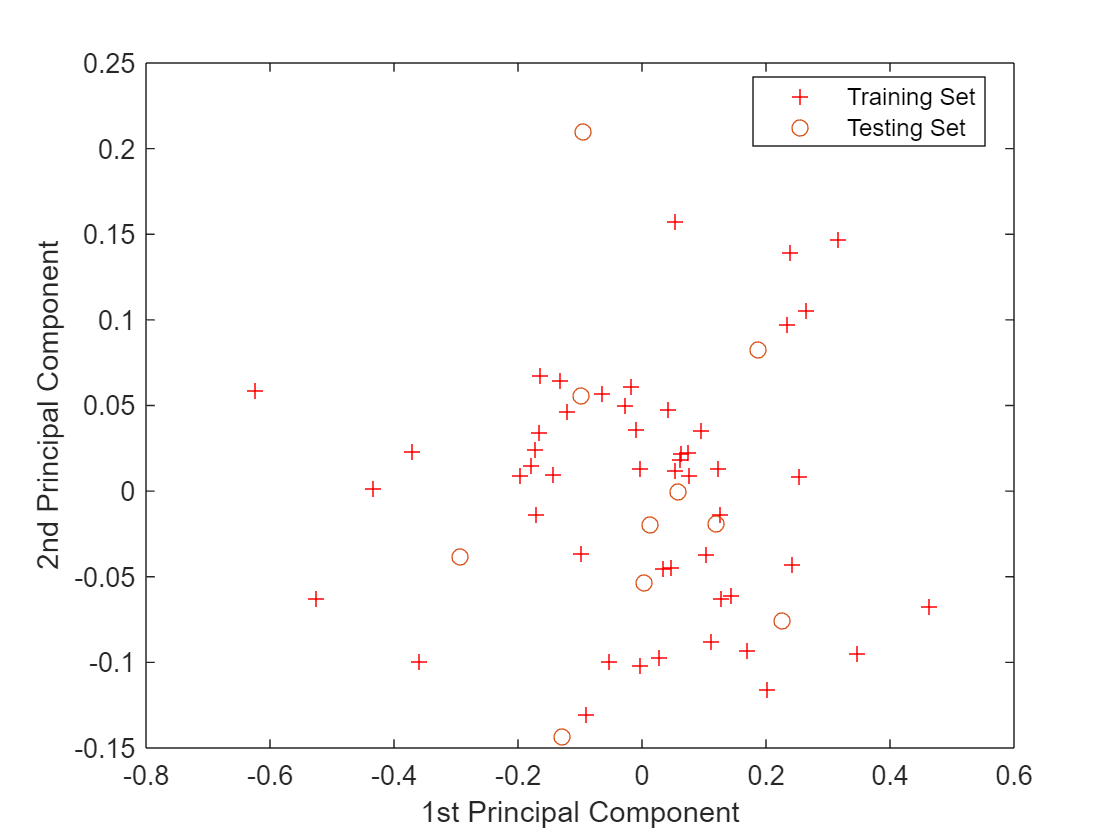

% 第一主成分vs.第二主成分
[PCALoadings,PCAScores,PCAVar] = pca(P_train);

figure
plot(PCAScores(:,1),PCAScores(:,2),'r+')
hold on

[PCALoadings_test,PCAScores_test,PCAVar_test] = pca(P_test);
plot(PCAScores_test(:,1),PCAScores_test(:,2),'o')

xlabel('1st Principal Component')
ylabel('2nd Principal Component')
legend('Training Set','Testing Set','location','best')

- **主成分回归模型创建**

k = 4;
betaPCR = regress(T_train-mean(T_train),PCAScores(:,1:k));
betaPCR = PCALoadings(:,1:k) * betaPCR;
betaPCR = [mean(T_train)-mean(P_train) * betaPCR;betaPCR];

- **主成分回归模型预测 **

N = size(P_test,1);
T_sim = [ones(N,1) P_test] * betaPCR;

- **结果分析与绘图**

% 相对误差error
error = abs(T_sim - T_test) ./ T_test;
%%
% 决定系数R^2
R2 = (N * sum(T_sim .* T_test) - sum(T_sim) * sum(T_test))^2 / ((N * sum((T_sim).^2) - (sum(T_sim))^2) * (N * sum((T_test).^2) - (sum(T_test))^2)); 
%%
% 结果对比
result = [T_test T_sim error]

result =    88.1000   88.0738    0.0003
   87.6000   87.3653    0.0027
   88.3500   88.3091    0.0005
   85.1000   85.0025    0.0011
   85.1000   85.3316    0.0027
   84.7000   84.5951    0.0012
   87.2000   87.5613    0.0041
   86.6000   86.9074    0.0036
   89.6000   89.2183    0.0043
   87.1000   87.0891    0.0001


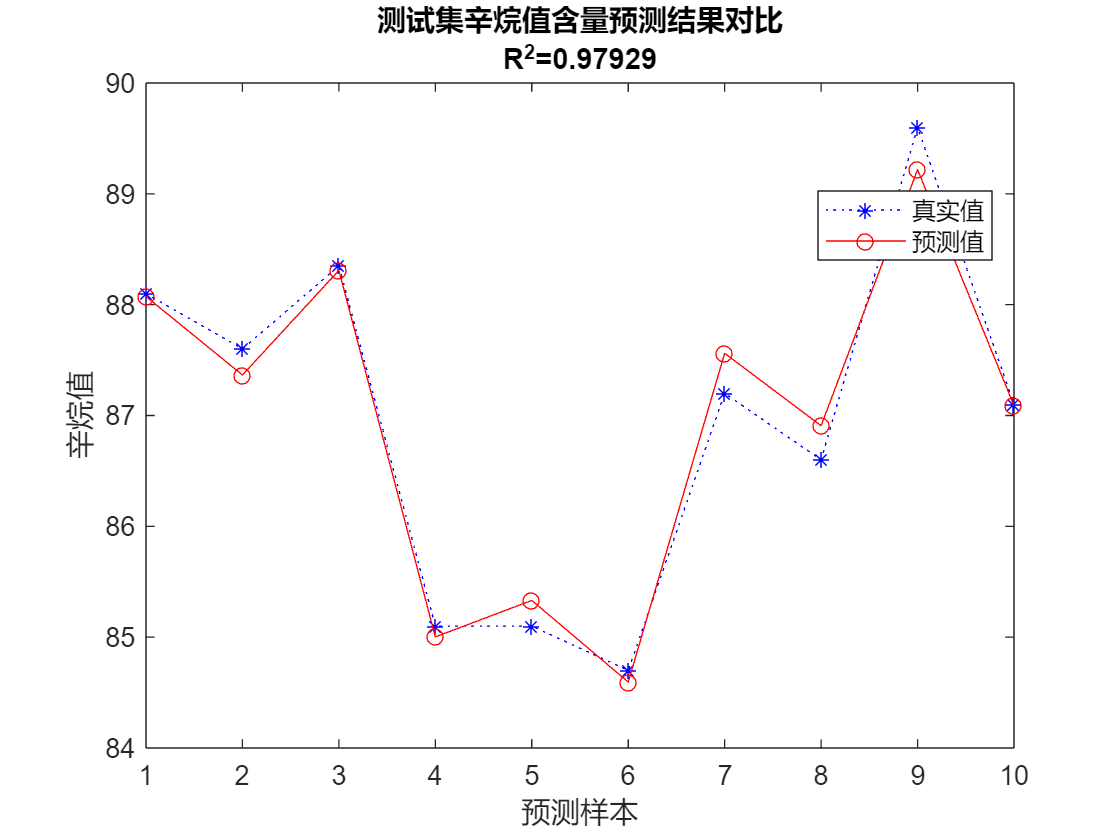

% 绘图
figure
plot(1:N,T_test,'b:*',1:N,T_sim,'r-o')
legend('真实值','预测值','location','best')
xlabel('预测样本')
ylabel('辛烷值')
string = {'测试集辛烷值含量预测结果对比';['R^2=' num2str(R2)]};
title(string)

## **7.5 案例2：基于PLS的的变量降维——近红外光谱汽油辛烷值预测**

- **导入数据、训练集/测试集划分部分与案例1相同**      

- **PLS回归模型创建**

[Xloadings,Yloadings,Xscores,Yscores,betaPLS,PLSPctVar,MSE,stats] = plsregress(P_train,T_train,k);

- **PLS回归模型预测**

N = size(P_test,1);
T_sim = [ones(N,1) P_test] * betaPLS;

- **结果分析与绘图**

% 相对误差error
error = abs(T_sim - T_test) ./ T_test;

% 决定系数R^2
R2 = (N * sum(T_sim .* T_test) - sum(T_sim) * sum(T_test))^2 / ((N * sum((T_sim).^2) - (sum(T_sim))^2) * (N * sum((T_test).^2) - (sum(T_test))^2)); 

% 结果对比
result = [T_test T_sim error]

result =    88.1000   88.2260    0.0014
   87.6000   87.4072    0.0022
   88.3500   88.5695    0.0025
   85.1000   85.3173    0.0026
   85.1000   85.5126    0.0048
   84.7000   84.4871    0.0025
   87.2000   87.8644    0.0076
   86.6000   87.0498    0.0052
   89.6000   89.4459    0.0017
   87.1000   87.3208    0.0025


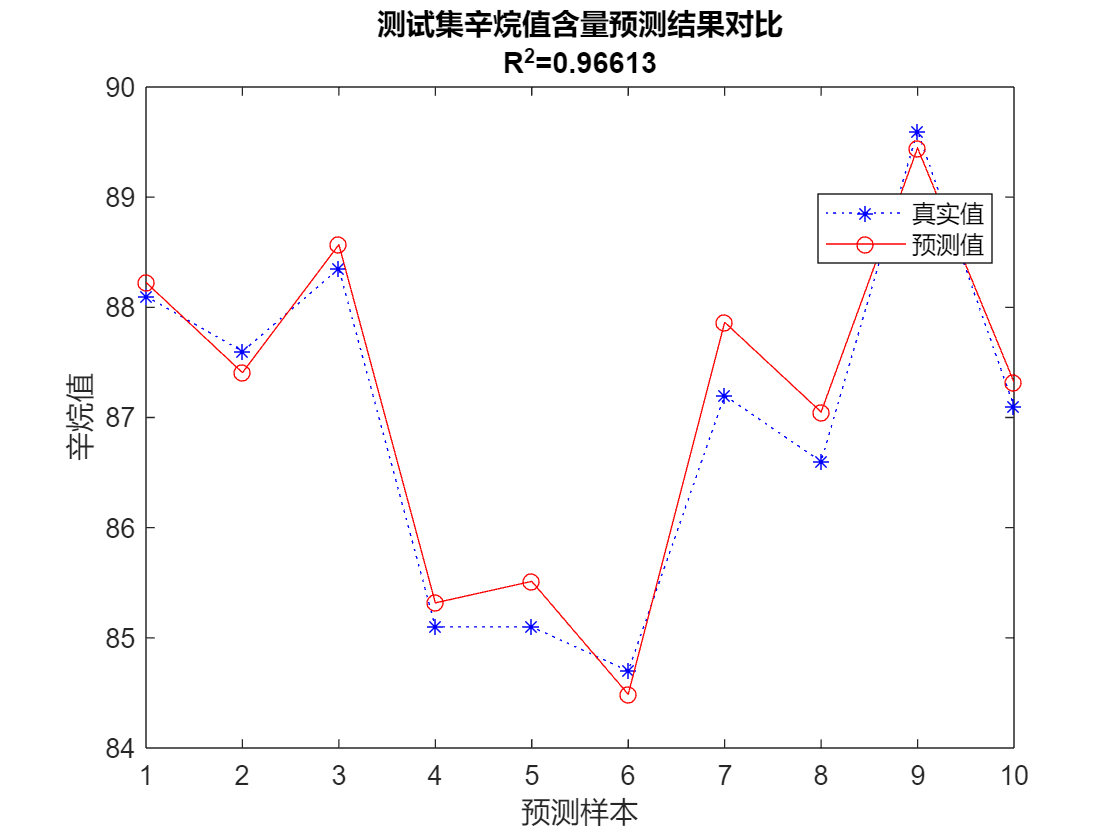

% 绘图
figure
plot(1:N,T_test,'b:*',1:N,T_sim,'r-o')
legend('真实值','预测值','location','best')
xlabel('预测样本')
ylabel('辛烷值')
string = {'测试集辛烷值含量预测结果对比';['R^2=' num2str(R2)]};
title(string)

## **7.6 案例3：基于遗传算法的特征选择**

- **声明全局变量**

global p_train t_train p_validation t_validation

- **导入数据部分于案例1相同**

- **随机划分训练集和测试集**

temp = randperm(size(NIR, 1));

% 训练集——40个样本
P_train = NIR(temp(1:40), 1:end-1)';
T_train = octane(temp(1:40), :)';

% 验证集——10个样本
P_validation = NIR(temp(41:50), 1:end-1)';
T_validation = octane(temp(41:50), :)';

% 测试集——10个样本
P_test = NIR(temp(51:end), 1:end-1)';
T_test = octane(temp(51:end), :)';

- **数据归一化        **

[p_train, ps_input] = mapminmax(P_train,0,1);
p_validation = mapminmax('apply',P_validation,ps_input);
p_test = mapminmax('apply',P_test,ps_input);

[t_train, ps_output] = mapminmax(T_train,0,1);
t_validation = mapminmax('apply',T_validation,ps_output);


- **初始化种群        **

initPop = randi([0 1], 20, 40);        % 产生初始化种群,种群规模20
fitnessVal = fitness(initPop);      % 计算每个个体适应度函数值
initPop = [initPop fitnessVal];


- **迭代优化        **

gen = 10;  % 遗传代数
newPop = initPop;

for i = 1:gen
    i
    % 选择
    [~, I] = sort(newPop(:,end), 'descend');   % 根据适应度函数值降序排列
    selectedPop = newPop(I(1:10),:);           % 选择排名前10的个体

    % 交叉
    for j = 1:20    % 循环产生新的种群
       temp = randperm(10,2);       % 随机选择两个个体 
       Individual_1 = selectedPop(temp(1),:);
       Individual_2 = selectedPop(temp(2),:);
       m = round(rand*40);  % 随机产生一个交叉点[2,39]
       newIndividual = [Individual_1(1:m) Individual_2(m+1:end-1)];
       newPop(j,:) = [newIndividual fitness(newIndividual)];
    end

    % 变异
    temp = randperm(20,2);       % 随机选择两个个体
    for k = 1:2
        n = randperm(40,5);          % 随机选择5个变异点
        for s = 1:5
            if newPop(temp(k),n(s)) == 0
                newPop(temp(k),n(s)) = 1;
            else
                newPop(temp(k),n(s)) = 0;
            end
        end
        newPop(temp(k),end) = fitness(newPop(temp(k),1:end-1));
    end
    
    [~, I] = sort(newPop(:,end), 'descend');
    bestPop(i,:) =  newPop(I(1),:);
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

- **输出寻优结果并绘图        **

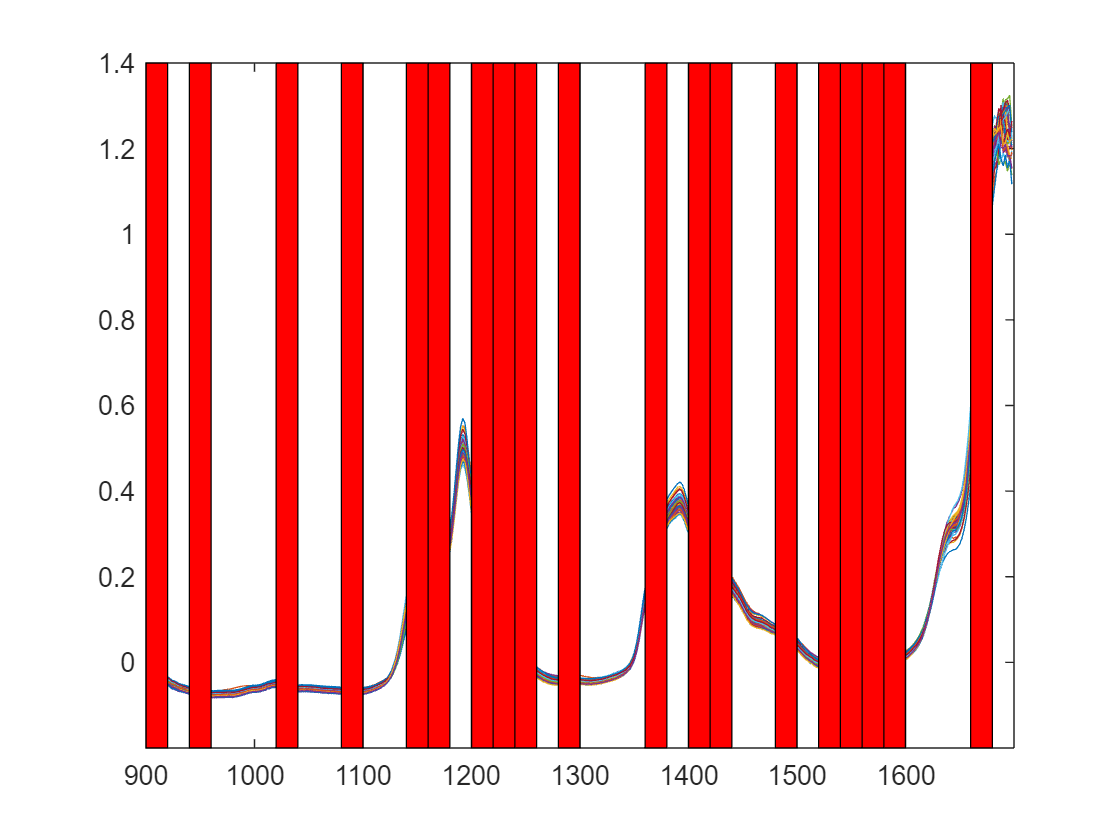

x = bestPop(end,1:end-1);

figure
plot(900:2:1698,NIR(:,1:400)')
hold on
[~, index] = find(x == 1);
for i = 1:length(index)
   fill([900+(index(i)-1)*20 900+index(i)*20 900+index(i)*20 900+(index(i)-1)*20],[-0.2 -0.2 1.4 1.4], 'r') 
end

- **利用筛选出的特征训练模型、预测及结果分析 **

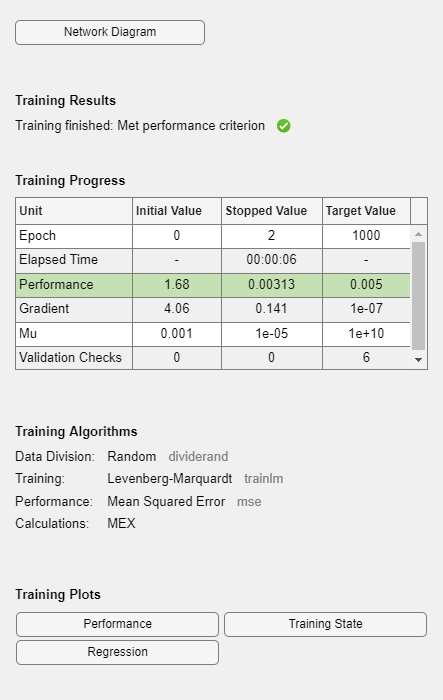

% 抽取筛选出的特征光谱
pn_train = [];
pn_test = [];
for i = 1:length(index)
    pn_train = [pn_train;p_train((index(i)-1)*10+1:index(i)*10,:)];
    pn_test = [pn_test;p_test((index(i)-1)*10+1:index(i)*10,:)];
end

% 创建网络
net = newff(pn_train, t_train, 10);

% 设置训练参数
net.trainParam.epochs = 1000;
net.trainParam.goal = 5e-3;
net.trainParam.lr = 0.01;

% 训练网络
net = train(net, pn_train, t_train);


% 仿真测试
t_sim = sim(net, pn_test);

% 数据反归一化
T_sim = mapminmax('reverse',t_sim,ps_output);

%% 性能评价
% 相对误差error
error = abs(T_sim - T_test)./T_test;

% 决定系数R^2
N = 10;
R2 = (N * sum(T_sim .* T_test) - sum(T_sim) * sum(T_test))^2 / ((N * sum((T_sim).^2) - (sum(T_sim))^2) * (N * sum((T_test).^2) - (sum(T_test))^2)); 

% 结果对比
result = [T_test' T_sim' error']

result =    88.5500   88.5883    0.0004
   88.1000   87.7870    0.0036
   88.7500   88.8815    0.0015
   87.0500   87.1092    0.0007
   85.1000   85.0042    0.0011
   86.5000   86.5796    0.0009
   87.6000   87.8401    0.0027
   87.3000   87.6689    0.0042
   87.9000   88.9647    0.0121
   89.6000   89.9925    0.0044


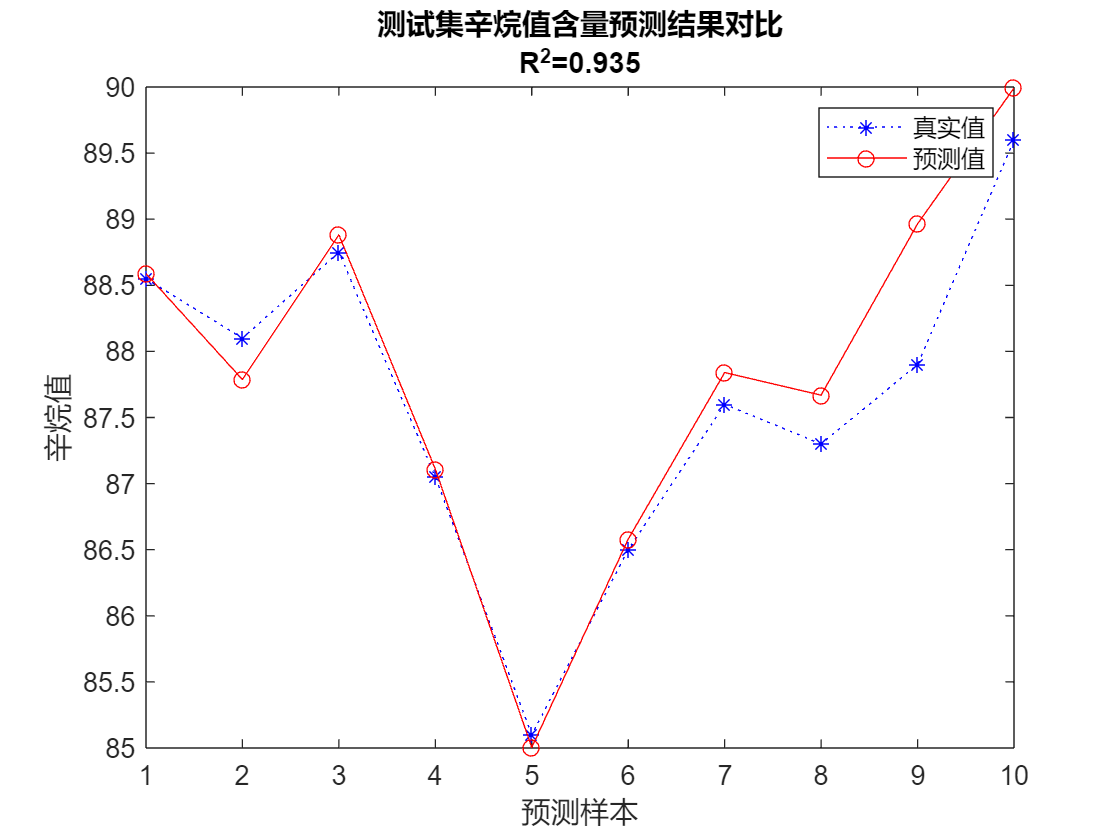


% 绘图
figure
plot(1:N,T_test,'b:*',1:N,T_sim,'r-o')
legend('真实值','预测值')
xlabel('预测样本')
ylabel('辛烷值')
string = {'测试集辛烷值含量预测结果对比';['R^2=' num2str(R2)]};
title(string)

## **Appendix：适应度子函数**

function fitnessVal = fitness(x)

    %% 声明全局变量
    global p_train t_train p_validation t_validation

    %% 遍历每个个体
    fitnessVal = zeros(size(x,1), 1);
    for k = 1:size(x,1)
        %% 根据x中“1”所在位置抽取变量
        [~, index] = find(x(k,:) == 1);

        pn_train = [];
        pn_validation = [];

        for i = 1:length(index)
            pn_train = [pn_train;p_train((index(i)-1)*10+1:index(i)*10,:)];
            pn_validation = [pn_validation;p_validation((index(i)-1)*10+1:index(i)*10,:)];
        end

        %% 利用抽取的变量建模
        % 创建网络
        net = newff(pn_train, t_train, 10);

        % 设置训练参数
        net.trainParam.epochs = 1000;
        net.trainParam.goal = 5e-3;
        net.trainParam.lr = 0.01;
        net.trainParam.showWindow = false;

        % 训练网络
        net = train(net, pn_train, t_train);

        % 仿真测试
        t_sim = sim(net, pn_validation);

        % 计算均方根误差
        SE = sqrt(sse(t_sim - t_validation)/10);
        % 遗传算法的适应值
        fitnessVal(k) = 1 / SE;
    end
end